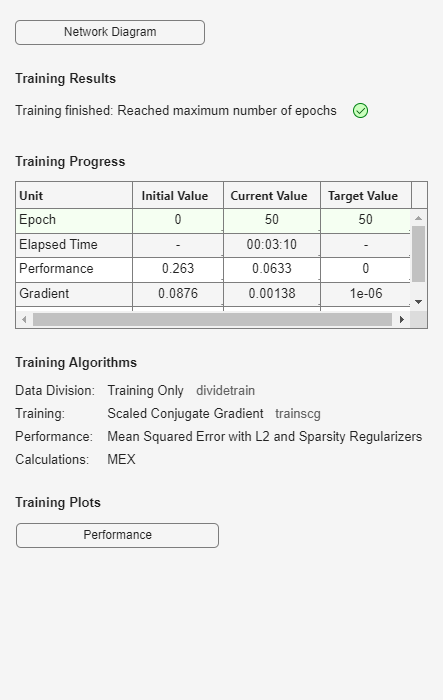

% Step 1: Load and Preprocess Data
train_data = readmatrix('mnist_train.csv');
test_data = readmatrix('mnist_test.csv');

% Separate labels and pixel values
train_labels = train_data(:, 1);
train_images = train_data(:, 2:end);
test_labels = test_data(:, 1);
test_images = test_data(:, 2:end);

% Normalize pixel values to [0, 1]
train_images = double(train_images) / 255;
test_images = double(test_images) / 255;

% Step 2: Reshape Data for Autoencoder
% trainAutoencoder expects a 2D matrix where columns are samples
train_images = train_images'; % Transpose so each column is a sample
test_images = test_images'; % Transpose so each column is a sample

% Step 3: Define and Train Autoencoder
hiddenSize = 64; % Size of the bottleneck layer
autoenc = trainAutoencoder(train_images, ...
    'MaxEpochs', 50, ...
    'L2WeightRegularization', 0.001, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.05);

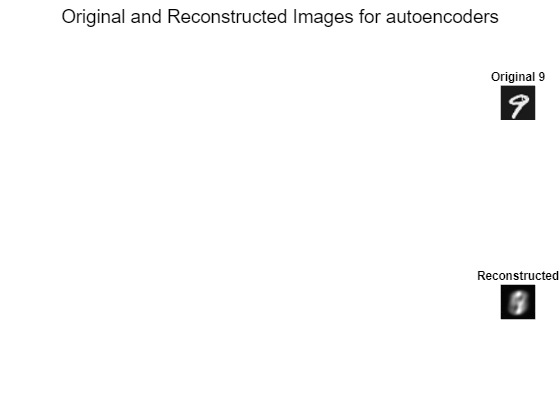

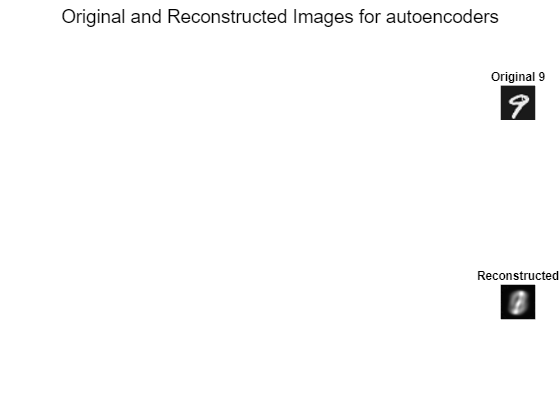

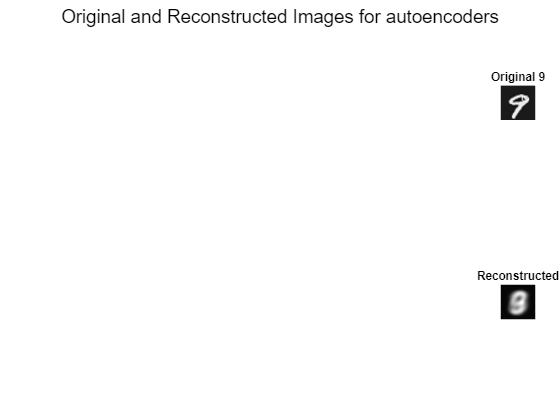

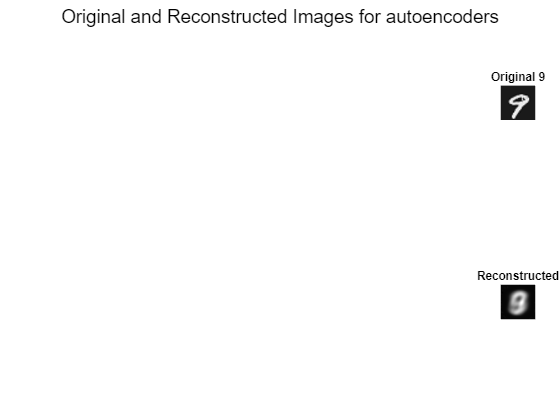

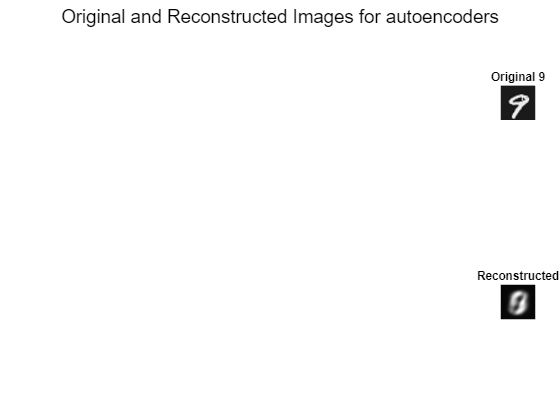

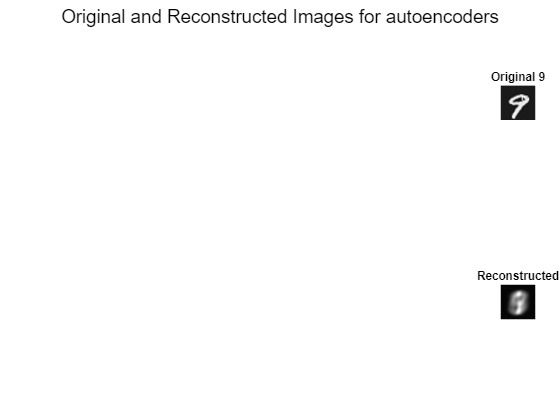

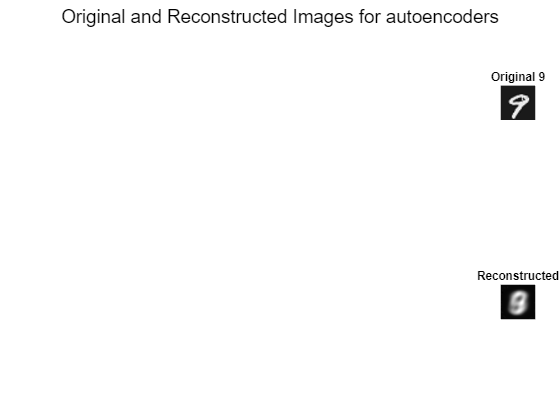

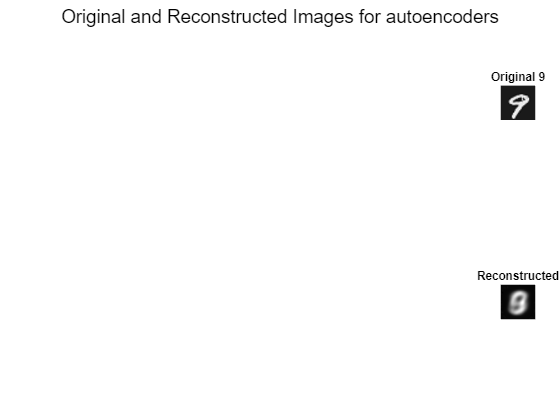



for j = 1:10
    % Step 4: Encode Test Data
    encoded_test_data = encode(autoenc, test_images);

     % Step 5: Simulate Fading Channel
    flat_data = encoded_test_data(:); % Flatten encoded data for transmission
    fading_coeff = (randn(size(flat_data)) + 1i * randn(size(flat_data))) / sqrt(2); % Rayleigh fading
    noisy_signal = fading_coeff .* flat_data;

    % Add Gaussian Noise
    snr = j; % Signal-to-noise ratio in dB
    noisy_signal = awgn(noisy_signal, snr, 'measured');

    % Receiver Side (Channel Equalization)
    received_signal = noisy_signal ./ fading_coeff; % Equalize fading
    received_encoded_data = reshape(real(received_signal), size(encoded_test_data)); % Reshape back

    % Step 6: Decode and Reconstruct Images
    reconstructed_images = decode(autoenc, received_encoded_data);

    % Reshape Reconstructed Images Back to Original Dimensions
    reconstructed_images = reconstructed_images';
    % Step 7: Visualize Original and Reconstructed Images
    numSamples = 10; % Number of test samples to visualize

    % Reshape test images and reconstructed images back to 28x28
    original_images = reshape(test_images', [], 28, 28);
    reconstructed_images = reshape(reconstructed_images, [], 28, 28);

    figure;

    % Adjust spacing parameters
    rows = 2; % Number of rows (original and reconstructed)
    cols = numSamples; % Number of columns
    spacing = 0.05; % Spacing factor between images
    for i = 1:numSamples
    % Rotate the original image
    original_img = squeeze(original_images(i, :, :));
    original_img = imrotate(original_img, -90); % Rotate to correct alignment
    original_img = fliplr(original_img);
    original_img = imresize(original_img, [500 500]);

    % Rotate the reconstructed image
    reconstructed_img = squeeze(reconstructed_images(i, :, :));
    reconstructed_img = imrotate(reconstructed_img, -90);% Rotate to correct alignment
    reconstructed_img = fliplr(reconstructed_img);
    reconstructed_img = imresize(reconstructed_img,[500 500]);

    % Display Original Image
    ax1 = subplot(rows, cols, i);
    imshow(original_img, []);
    title(['Original ' num2str(test_labels(i))]);

    % Adjust position for spacing
    pos1 = get(ax1, 'Position');
    pos1(1) = pos1(1) + spacing; % Adjust horizontal spacing
    set(ax1, 'Position', pos1);

    % Display Reconstructed Image
    ax2 = subplot(rows, cols, i + cols);
    imshow(reconstructed_img, []);
    title('Reconstructed');

    % Adjust position for spacing
    pos2 = get(ax2, 'Position');
    pos2(1) = pos2(1) + spacing; % Adjust horizontal spacing
    set(ax2, 'Position', pos2);
    
    end

    sgtitle('Original and Reconstructed Images for autoencoders');
end

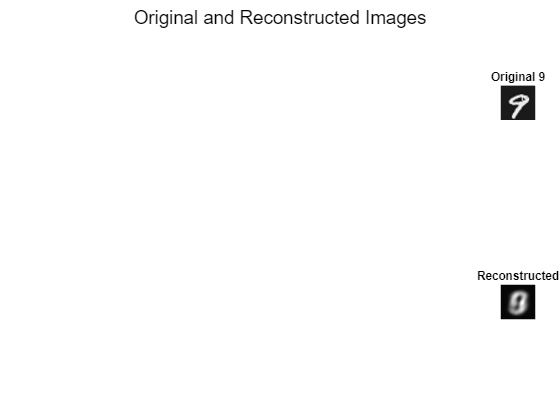

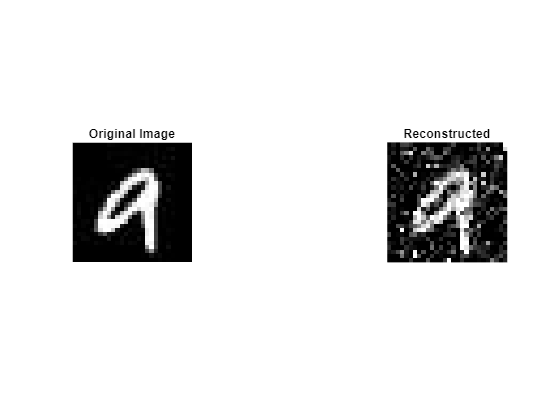

% Step 1: Import the Image
original_image = imread('C:\Users\HP\Desktop\img_349.jpg'); % Replace with your image file

% Step 2: JPEG Compression (Encoder Side)
jpeg_quality = 20; % Compression quality
imwrite(original_image, 'compressed_image.jpg', 'Quality', jpeg_quality);
compressed_image = imread('compressed_image.jpg');

% Step 3: Flatten Image to Simulate Transmission
image_data = double(compressed_image(:)); % Flatten image to a vector

% Step 4: Pass Through Fading Channel
% Simulate Rayleigh Fading Channel
fading_coeff = (randn(size(image_data)) + 1i * randn(size(image_data))) / sqrt(2); % Rayleigh fading
noisy_signal = fading_coeff .* image_data;

% Add Gaussian Noise to simulate channel noise
snr = 3; % Signal-to-noise ratio in dB
noisy_signal = awgn(noisy_signal, snr, 'measured'); 

% Receiver Side (Channel Equalization)
received_signal = noisy_signal ./ fading_coeff; % Equalize fading
received_image = uint8(real(received_signal)); % Convert back to uint8

% Reshape the received image to original dimensions
reconstructed_image = reshape(received_image, size(compressed_image));

% Step 5: Display Reconstructed Image with Spacing

% Create figure with subplots and spacing
figure;


% Original Image
subplot(1, 3, 1); % Place in the first column
imshow(original_image);
title('Original Image');



% Reconstructed Image After Fading Channel
subplot(1, 3, 3); % Place in the third column
imshow(reconstructed_image);
title('Reconstructed');